# Nonlinear Adaptive Control

## Nonlinear Pendulum continuous model simulation

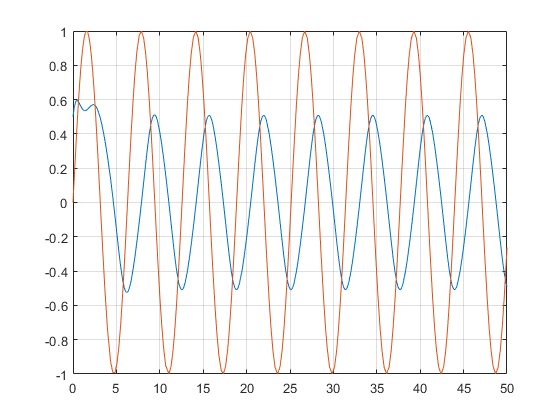

[t, y] = ode23(@pendulum, [0 50], [0.5 0.5]);

figure,
plot(t, y(:, 1)); grid; hold on;
plot(t, sin(t));

## Nonlinear Pendulum discrete model simulation

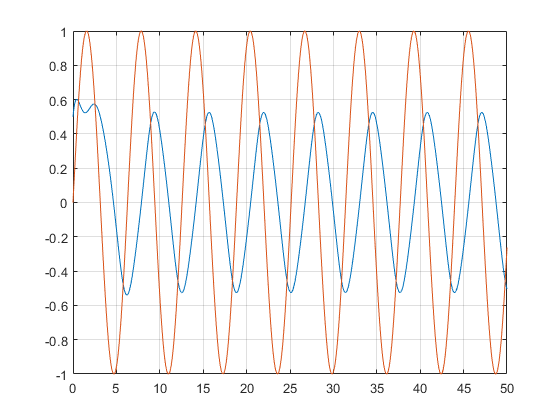

Ts = 0.05;
t = 0:Ts:50;
u = sin(t);
x = zeros(2, length(t));
x(:, 1) = [0.5; 0.5];
a = -5;
b = -2;

for i = 1:length(t) - 1
    x(:, i + 1) = x(:, i) + Ts*pendulum_derivative(x(:, i), u(i), a, b);
end

figure, 
plot(t, x(1, :)); grid; hold on;
plot(t, u);

## Neural Network Based Adaptive Control

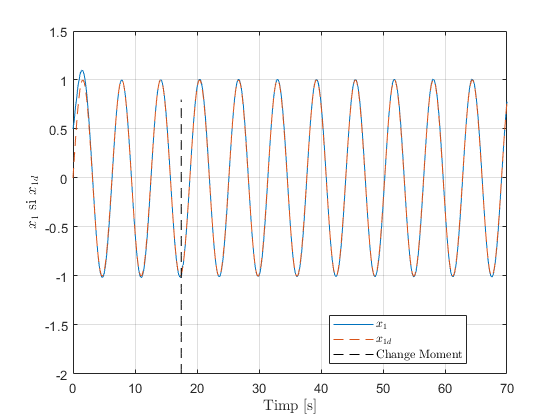

a = -5;
b = -2;
Ac = diag([-20 -20]);
x0 = [0.5 0.5]';
lr = 25;
gamma = 0.001;

Ts = 0.05;
t = 0:Ts:70;
% desired trajectory
xd = [sin(t); cos(t)];

m = 20; % number of hidden neurons
n = 4; % number of inputs

% neural network weights
Vc = rands(m, n);
Wc = rands(1, m);

x = zeros(2, length(t));
e = zeros(2, length(t));

x(:, 1) = x0;
u = zeros(length(t), 1);

aux = floor(length(t)/2)/2;

for i = 1:length(t) - 1
    if i == aux
        a = a - 5;
        b = b + 3;
    end
    
    e(:, i) = x(:, i) - xd(:, i);
    x_cnn = [e(:, i); xd(:, i)];
    
    % backpropagation
    dWc = e(:, i)'/Ac*ones(2, 1)*tanh(Vc*x_cnn)';   
    duda = Wc*(eye(m) - diag(tanh(Vc*x_cnn).^2)); % Wc.*tanh_derivative(Vc*x_cnn)'
    dVc = (e(:, i)'/Ac*ones(2, 1)*duda)'*x_cnn';
    
    Wc = Wc - lr*dWc - gamma*norm(e(:, 1))*Wc;
    Vc = Vc - lr*dVc - gamma*norm(e(:, 1))*Vc;
    
    % inference
    u(i) = -Wc*tanh(Vc*x_cnn);
    
    x(:, i + 1) = x(:, i) + Ts*pendulum_derivative(x(:, i), u(i), a, b);    
end

figure, 
plot(t, x(1, :)); hold on; grid;
plot(t, xd(1, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_1$ si $x_{1d}$", "Interpreter","latex");
legend("$x_1$", "$x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

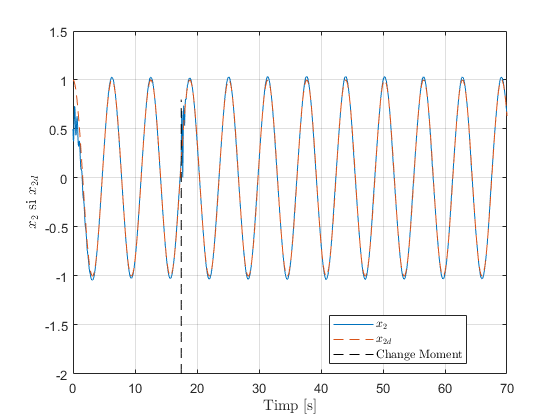


figure, 
plot(t, x(2, :)); hold on; grid;
plot(t, xd(2, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_2$ si $x_{2d}$", "Interpreter","latex");
legend("$x_2$", "$x_{2d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

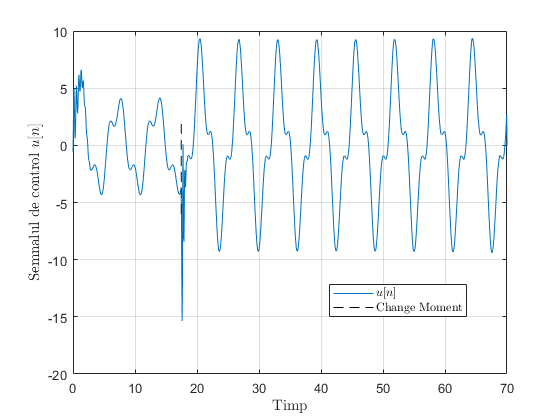


figure,
plot(t, u); grid; hold on;
plot(t(aux)*ones(length(t), 1), t*0.12 - 6, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("Semnalul de control $u[n]$", "Interpreter","latex");
legend("$u[n]$", "Change Moment", "Interpreter", "Latex", "Location","best");

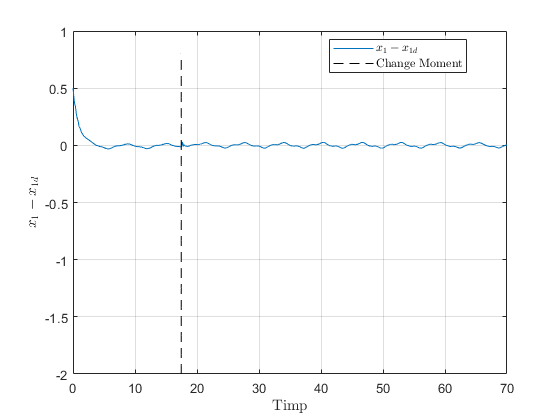


figure, 
plot(t, e(1, :)); grid; hold on;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("$x_1 - x_{1d}$", "Interpreter","latex");
legend("$x_1 - x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

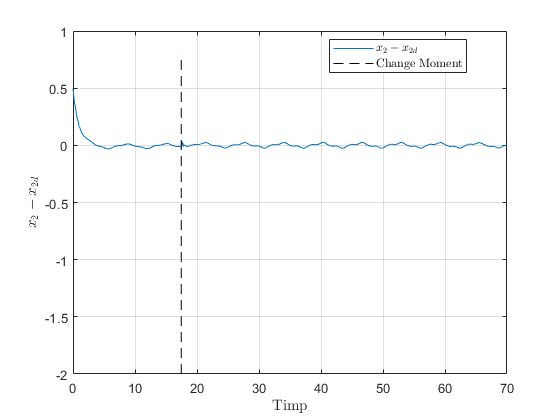


figure, 
plot(t, e(1, :)); grid; hold on;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("$x_2 - x_{2d}$", "Interpreter","latex");
legend("$x_2 - x_{2d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

function dx = pendulum(t, x)
    u = sin(t);
    a = -5;
    b = -2;
    
    dx = pendulum_derivative(x, u, a, b);
end

function dx = pendulum_derivative(x, u, a, b)
    dx = [x(2);
          a*x(1)^3 + b*x(2) + u];
end